## Семинар 11. Метод анализа главных компонент. Векторные пространства.

На протяжении следующих трех-четырех семинаров мы будем решать следующую задачу: 

Как, имея таблицу данных с результатами измерения разных свойств, например, таблицу трендов по времени для свойств материала, вытащенных из базы данных за некоторый период времени, понять какие из свойств являются линейно коррелированными. 

## PCA - principal component analysis (анализ главных компонент)

PCA - способ анализа степени "независимости" столбцов матрицы. Позволяет понять есть ли среди данных "лишние", то есть не несущие информации, понять как нужно преобразовать исходные данные, чтобы они были максимально линейно независимыми. Позволяет уменьшить размерность данных. 

Применяется во многих разделах анализа данных, таких как, классификация, сжатие  и распознавание изображений, корреляционный анализ и др. Часто используется в машинном обучении, когда надо "прорядить" исходные данные обучающей выборки для нейронных сетей.

## Немного о матрицах.

#### Матрица A размером nxm это:

- Упорядоченная коллекция чисел: $A(i,j)$ => индексирование (get_index, set_index)

- Упорядоченная коллекция вектор-столбцов: $A = [\vec{a_1},...,\vec{a_i},...,\vec{a_m}]$, $A(:,i)=\vec{a_i}$ => итерирование по столбцам матрицы в цикле

- Оператор линейного преобразования векторов, символ  $[A]$ - обозначает "действие" матрицы: $A\vec{b} = \vec{c}$ <=> подействовав матрицей $A$ на вектор $\vec{b}$ мы преобразовали его в вектор $\vec{c}$ 

- Совокупность $m$ вектор-столбцов (в каждом из которых $N$ координат) $A = [\vec{a_1},...,\vec{a_i},...,\vec{a_m}]$  - это линейное подпространство векторного пространства $R^N$ всех векторов размером $N$, обозначается как $span\{A\}$

- Совокупность 

Сингулярная матрица - матрица,  у которой колонки (или строки) являются зависимыми (либо равными нулю), то есть могут быть выражены как линейная комбинация других строк (колонок) этой же матрицы. 

Ранг матрицы  - количество ее линейно-независимых столбцов (строк)

Для сингулярной матрицы $A$размером $ [N\times M] $, размерность линейного подпространства  ее столбцов $span\{A\}$  меньше размерности линейного пространства $R^N$.

#### Как понять насколько сильно отличаются два вектора друг от друга?

Косинус угла между ними!

Косинус угла между двумя векторами:

$cos( \alpha) =\frac  {\vec a \cdot \vec b } {|\vec a | |\vec b |} =\hat a \cdot\frac  {\vec b } { |\vec b |} =\hat{a}^T \frac  {\vec b } { |\vec b |} $                                                                                                                                                            (*)

$\hat a$ - единичный вектор, направленный вдоль $\vec a
$

Чем меньше косинус угла между векторами, тем они больше друг от друга отличаются (для ортогональных векторов он равен нулю), чем ближе косинус (по модулю)   к единице, тем  более "похожи" вектора друг на друга, так как $cos( \alpha) =\frac  {\vec a \cdot \vec b } {|\vec a | |\vec b |}$

#### Проекция вектора на вектор

У вектора $\vec{b}$ есть зависимая от $\vec{a}$ компонента $\vec{b_{|| \vec{a}} }$, то есть та, которая может быть получена путем умножения $\vec{a}$ на число  и полностью независимая компонента $ \vec{b}_{\perp\vec{a}}}$ ортогональная вектору  $\vec{a}$.


$$\vec{b}=\vec{b_{|| \vec{a}} } + \vec{b}_{\perp\vec{a}}}$$


$\vec{b_{|| \vec{a}} }=\hat{a}|\vec{b}|cos(\alpha)=\hat{a} |\vec{b}| \hat{a}\cdot \frac  { \vec b } {|\vec b |}= \hat{a}( \hat{a}^T\vec{b})$ - вектор проекции вектора $\vec{b}$ на направление вектора $\vec{a}$ - показывает зависимую от $\vec{a}$ долю вектора $\vec{b}$ 

$\vec{b}_{\perp\vec{a}}=\vec{b} - \vec{b_{|| \vec{a}} } =\vec{b} - \hat{a}( \hat{a}^T\vec{b})$ - характеризует независимую от  вектора $\vec{a}$ составляющую вектора  $\vec{b}$                                     (**)

clearvars
a_vec = rand(2,1) % генерим случайный вектор на плоскости

a_vec =     0.4585
    0.5779


% Проекция веткоров 
R =[78.511;0.73] % координаты вектора в сферической системе координат 

R =    78.5110
    0.7300


% угол - модуль
ang = deg2rad(R(1)); %угол вектора
module = R(2);% модуль вектора
b_vect = [module*cos(ang);module*sin(ang)];
a_hat = a_vec/norm(a_vec) %- единичный вектор вдоль а 

a_hat =     0.6215
    0.7834


b_par = a_hat*(transpose(a_hat)*b_vect) % проекция вектора b на вектор а

b_par =     0.4045
    0.5099


b_per = b_vect  - b_par % составляющяа вектора b перпендикуларная вектору а

b_per =    -0.2591
    0.2055


fig1


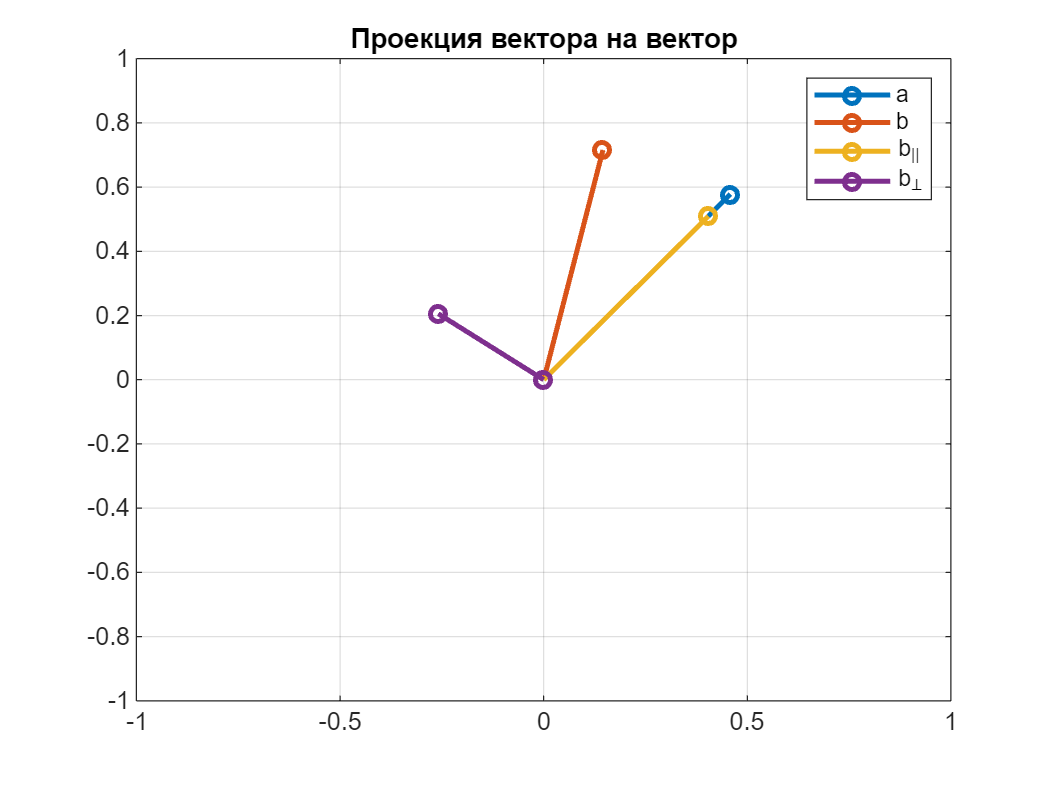

draw_vector([],'Проекция вектора на вектор',["a" "b" "b_{||}" "b_{\perp}"],"vector",a_vec,b_vect, b_par,b_per);

disp("(b_parallel^T)*b_perpendicular = " + transpose(b_per)*b_par)

(b_parallel^T)*b_perpendicular = 6.9389e-17


А что, если в выражении (**) взять и "вынести вектор" $\vec{b}$ за скобки

 $\vec{b}_{\perp\vec{a}} = (I- \hat{a} \hat{a}^T)\vec{b}=(I-P_{\vec{a}})\vec{b}$  - составляющая вектора $\vec{b}$, перпендикулярная вектору $\vec{a}$, получается действием матрицы $T=(I-P_{\vec{a}})$ на вектор $\vec{b}$

 $P_{a} = \hat{a} \hat{a}^T$ - оператор проецирования произвольного вектора на вектор $\vec{a}$ - внешнее скалярное произведение


$$\vec{b_{|| \vec{a}} }=P_{a}\vec{b}$$


a = sym("a1",[3 1])

$$a = \left(\begin{array}{c} a_{11}\\ a_{12}\\ a_{13} \end{array}\right)$$

a*transpose(a)

$$ans = \left(\begin{array}{ccc} {a_{11}}^{2} & a_{11}\,a_{12} & a_{11}\,a_{13}\\ a_{11}\,a_{12} & {a_{12}}^{2} & a_{12}\,a_{13}\\ a_{11}\,a_{13} & a_{12}\,a_{13} & {a_{13}}^{2} \end{array}\right)$$

% посчитаем проекции через матричные операторы
P = a_hat*transpose(a_hat) % оператор проецирования 

P =     0.3863    0.4869
    0.4869    0.6137


b_per2 = (eye(2)-P )*b_vect

b_per2 =    -0.2591
    0.2055


b_par2 = P*b_vect 

b_par2 =     0.4045
    0.5099



$$\vec{b_{|| \vec{a}} } \cdot \vec{b}_{\perp\vec{a}}=\vec{b_{|| \vec{a}} }^T\vec{b}_{\perp\vec{a}}=\vec{b}^TP_{a}^T(I-P_{a})\vec{b}=0$$


#### Проекция вектора на векторное подпространство

Теперь рассмотрим два вектора $\vec{a}_1$ и $\vec{a}_2$, они образуют плоскость (в трехмерном пространстве), на эту плоскость можно спроецировать вектор $\vec{b}$

$\vec{b_{|| \vec{a}_1} }=P_{a_1}\vec{b}$ - проекция вектора $\vec{b}$ на вектор $\vec{a}_1$

$\vec{b_{|| \vec{a}_2} }=P_{a_2}\vec{b}$- проекция вектора $\vec{b}$ на вектор $\vec{a}_2$


$$\vec{\beta}_{||\enspace\vec{a_1}, \vec{a}_2 } =(P_{a_2}+ P_{a_2})\vec{b}$$


Если ввести матрицу $A=[\vec{a_1},\vec{a_2}]$, то оператор $AA^T$ будет давать вектор $\vec{\beta}_{||\enspace\vec{a_1}, \vec{a}_2 }$, лежащий в плоскости вектор-столбцов этой матрицы:


$$\vec{\beta}_{||\enspace\vec{a_1}, \vec{a}_2 }=(P_{a_2}+ P_{a_2})\vec{b} = (\hat{a_1} \hat{a_1}^T+ \hat{a_2} \hat{a_2}^T)\vec{b}=AA^T\vec{b}$$



$$P_{a_1,a_2} = P_{a_2}+ P_{a_2} = AA^T$$


% Проверка формул выше через символьные вычисления
a1 = sym("a1",[3 1],'real') % вектор-столбец

$$a1 = \left(\begin{array}{c} a_{11}\\ a_{12}\\ a_{13} \end{array}\right)$$

a2 = sym("a2",[3 1],'real') % вектор-столбец

$$a2 = \left(\begin{array}{c} a_{21}\\ a_{22}\\ a_{23} \end{array}\right)$$

b = sym("b",[3,1],'real') % вектор-столбец

$$b = \left(\begin{array}{c} b_{1}\\ b_{2}\\ b_{3} \end{array}\right)$$

Pa1a2  = (a1*a1' + a2*a2') % сумма операторов проектирования

$$Pa1a2 = \left(\begin{array}{ccc} {a_{11}}^{2}+{a_{21}}^{2} & a_{11}\,a_{12}+a_{21}\,a_{22} & a_{11}\,a_{13}+a_{21}\,a_{23}\\ a_{11}\,a_{12}+a_{21}\,a_{22} & {a_{12}}^{2}+{a_{22}}^{2} & a_{12}\,a_{13}+a_{22}\,a_{23}\\ a_{11}\,a_{13}+a_{21}\,a_{23} & a_{12}\,a_{13}+a_{22}\,a_{23} & {a_{13}}^{2}+{a_{23}}^{2} \end{array}\right)$$

A = [a1,a2] % матрица из двух вектор-столбцов

$$A = \left(\begin{array}{cc} a_{11} & a_{21}\\ a_{12} & a_{22}\\ a_{13} & a_{23} \end{array}\right)$$

Pa1a2_mat = A*A' % сумма матриц проектирования 

$$Pa1a2\_mat = \left(\begin{array}{ccc} {a_{11}}^{2}+{a_{21}}^{2} & a_{11}\,a_{12}+a_{21}\,a_{22} & a_{11}\,a_{13}+a_{21}\,a_{23}\\ a_{11}\,a_{12}+a_{21}\,a_{22} & {a_{12}}^{2}+{a_{22}}^{2} & a_{12}\,a_{13}+a_{22}\,a_{23}\\ a_{11}\,a_{13}+a_{21}\,a_{23} & a_{12}\,a_{13}+a_{22}\,a_{23} & {a_{13}}^{2}+{a_{23}}^{2} \end{array}\right)$$

b_par = Pa1a2*b

$$b\_par = \begin{array}{l} \left(\begin{array}{c} b_{2}\,\sigma_{3}+b_{3}\,\sigma_{2}+b_{1}\,\left({a_{11}}^{2}+{a_{21}}^{2}\right)\\ b_{1}\,\sigma_{3}+b_{3}\,\sigma_{1}+b_{2}\,\left({a_{12}}^{2}+{a_{22}}^{2}\right)\\ b_{1}\,\sigma_{2}+b_{2}\,\sigma_{1}+b_{3}\,\left({a_{13}}^{2}+{a_{23}}^{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{12}\,a_{13}+a_{22}\,a_{23}\\ \sigma_{2}=a_{11}\,a_{13}+a_{21}\,a_{23}\\ \sigma_{3}=a_{11}\,a_{12}+a_{21}\,a_{22} \end{array}$$

b_par2 = Pa1a2_mat*b

$$b\_par2 = \begin{array}{l} \left(\begin{array}{c} b_{2}\,\sigma_{3}+b_{3}\,\sigma_{2}+b_{1}\,\left({a_{11}}^{2}+{a_{21}}^{2}\right)\\ b_{1}\,\sigma_{3}+b_{3}\,\sigma_{1}+b_{2}\,\left({a_{12}}^{2}+{a_{22}}^{2}\right)\\ b_{1}\,\sigma_{2}+b_{2}\,\sigma_{1}+b_{3}\,\left({a_{13}}^{2}+{a_{23}}^{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=a_{12}\,a_{13}+a_{22}\,a_{23}\\ \sigma_{2}=a_{11}\,a_{13}+a_{21}\,a_{23}\\ \sigma_{3}=a_{11}\,a_{12}+a_{21}\,a_{22} \end{array}$$

b_par - b_par2

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

Вектор $\vec{\beta}_{||\enspace\vec{a_1}, \vec{a}_2 }$ суммы проекций лежит в плоскости векторов $\vec{a}_1$ и $\vec{a}_2$, но он, в общем случае, по модулю не равен проекции $\vec{b}_{|| \vec{a}_1, \vec{a}_2} }$  вектора  $\vec{b}$ на плоскость векторов $\vec{a}_1$ и $\vec{a}_2$.

Зато, мы теперь можем спроецировать исходный вектор на него:


$$\vec{b_{|| \vec{a}_1} }=P_{\beta}\vec{b}$$


Если бы исходные вектора были бы ортонормированы, то :


$$\vec{\beta}_{||\enspace\vec{a_1}, \vec{a}_2 }=\vec{b}_{||\enspace\vec{a_1}, \vec{a}_2 }$$


% Проекция вектора на пространство столбцов матрицы из двух столбцов
 
clearvars
% генерим случаные вектора в трехмерном пространстве
a1 = 2*(0.5 - rand(3,1)); 
a2 = 3*(0.5 - rand(3,1));
R = [0.72, -50.7,161.3 ];% модуль-тетта-фи - сферическая система координат дял трехмерного вектора
r = R(1);thetta = R(2);phi = R(3);
b = [r*cosd(thetta)*sind(phi);r*cosd(thetta)*cosd(phi);r*sind(thetta)] % некоторый вектор

b =     0.1462
   -0.4320
   -0.5572


A = [a1,a2]

A =    -0.7321    0.3762
    0.3053   -0.2447
   -0.7053   -1.2368


%norm(A)
[bpar,bper,ang] = projection_matrix(A,b);
disp("bpar'*bper =" + ...
    transpose(bpar)*bper)

bpar'*bper =1.0408e-17


fig2


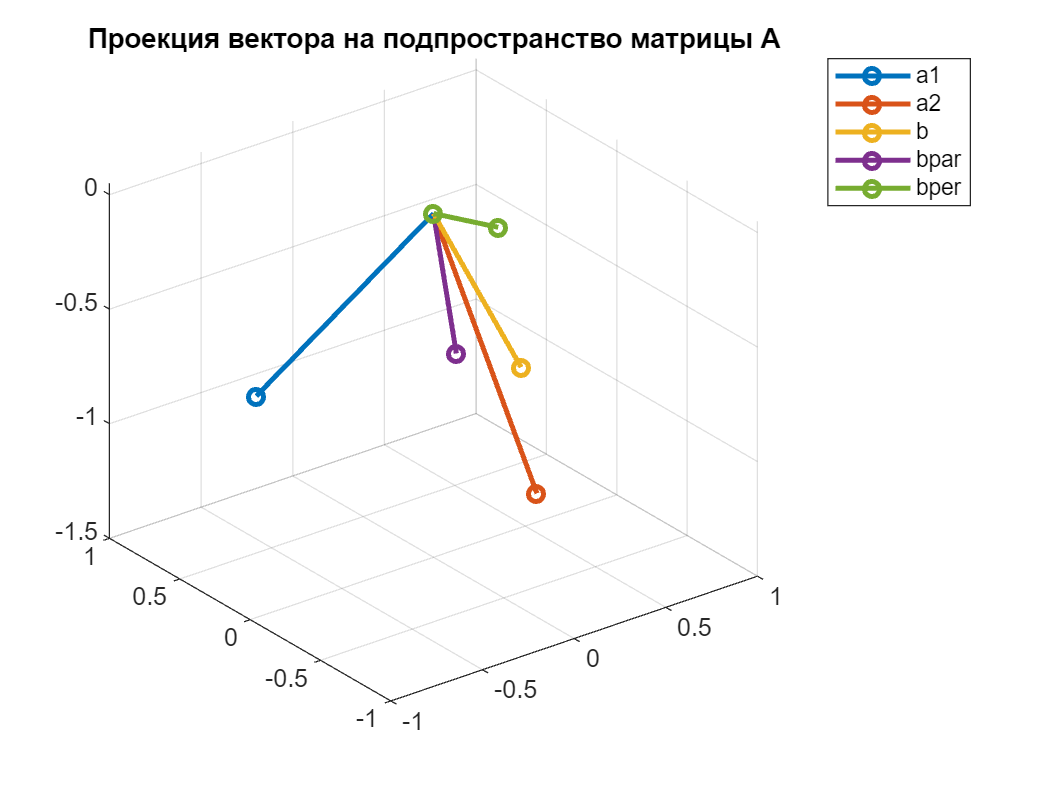


draw_vector([],'Проекция вектора на подпространство матрицы A',["a1" "a2" "b" "bpar" "bper"],"vector",a1,a2, b,bpar,bper);

ang

ang = 31.3838

ang2 = rad2deg(subspace(A,b)) 

ang2 = 24.6867

% функция subspace позволяет посчитать угол между двумя подпространствами
% для нее b - не обязательно вектор, но может быть и матрицей

clearvars
a1 = 0.5 - rand(2,1);
%a2 = 0.5 - rand(2,1);


 
R1 = [0.62,235.9 ];
r = R1(1);
thetta = R1(2);
%phi = R1(3);

make_singular = false;
if make_singular
    a2=0.3*a1; % чтобы матриц стала сингулярной 
else
    a2 = [r*cosd(thetta);r*sind(thetta)];
    
end
A = [a1,a2];
theta = rad2deg(subspace(a1,a2)) % subspace - функция, которая возвращает угол между подпространствами  

theta = 67.5095

fig3


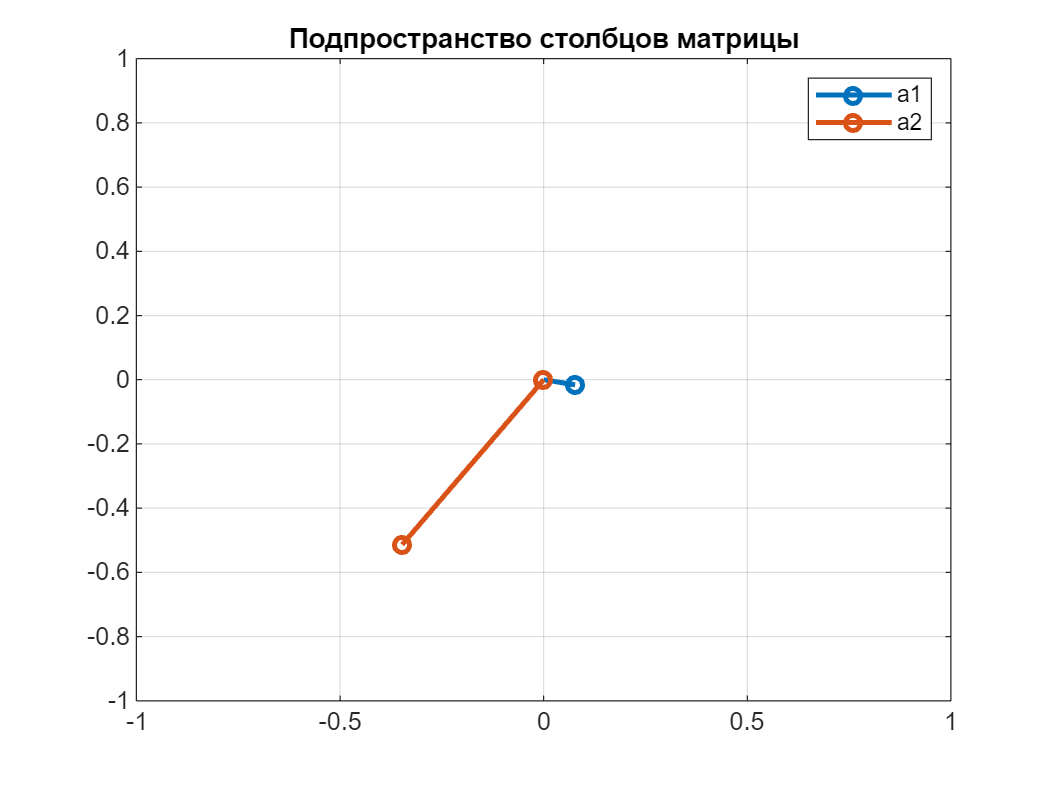

ax1 = draw_vector([],'Подпространство столбцов матрицы',["a1" "a2"],"vector",a1,a2);

disp("Определитель матрицы А:" + det(A))

Определитель матрицы А:-0.044987


disp("SVD спектр матрицы А:" + join(string(svds(A,3))))

SVD спектр матрицы А:0.62074 0.072473


disp("Спектр собственных значений матрицы A:" + join(string(eigs(A,3))))

Спектр собственных значений матрицы A:-0.52256 0.086089


fig4


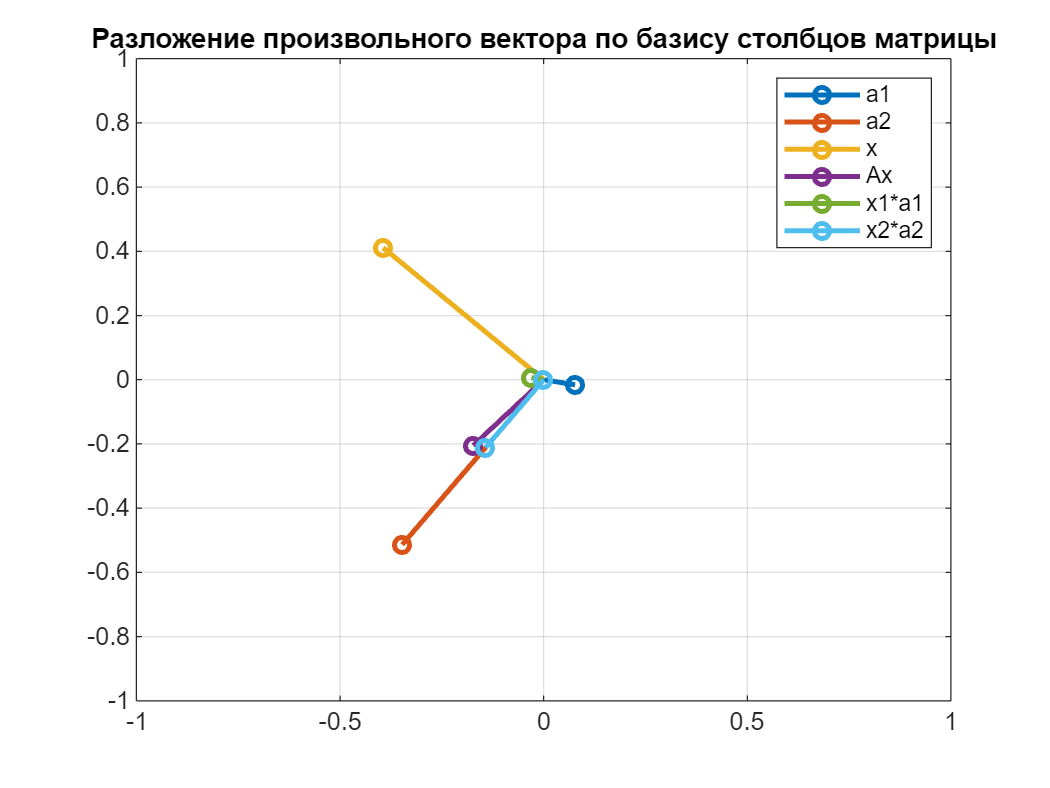

R = [0.57, 133.8];
r = R(1);thetta = R(2);
X = [r*cosd(thetta);r*sind(thetta)];
draw_vector([],'Разложение произвольного вектора по базису столбцов матрицы', ...
    ["a1" "a2" "x" "Ax" "x1*a1" "x2*a2"], ...
    "vector",a1,a2, X,A*X,X(1)*a1,X(2)*a2);

theta = subspace(A,X);
disp("Угол между подпространством столбцов матрицы и вектором X = " + rad2deg(theta))

Угол между подпространством столбцов матрицы и вектором X = 8.996e-15


disp("Угол между Ax и x: " + rad2deg(subspace(A*X,X)))

Угол между Ax и x: 84.0213


disp("Изменение длины вектора |Ax|/|x| = " + norm(A*X)/norm(X))

Изменение длины вектора |Ax|/|x| = 0.47097


%ДАЛЬШЕ ИДУТ ФУНКЦИИ
function ax = draw_vector(ax,ttl,names,type,varargin)
% функция строит двух- и трех-мерные вектора, а также рассеянные данные из
% матрицы
% ax - оси (если пустые, то создаются новые)
% ttl - заголовок картинки
% names - имена векторов
% type:
%       "vector" - аргументы, которые передаются после интерпретируются
%                   как отдельные вектора
%       "point"  - в этом случае передается матрица в качестве аргумента и
%       столбцы матрицы строятся при помощи функций scatter и scatter3 d
%       в зависимости от размерности массива
    arguments
        ax =[]
        ttl string =strings(0,1)
        names string =strings(0,1)
        type string {mustBeMember(type,["vector" "point"])}="vector"
    end
    arguments (Repeating)
        varargin double
    end
    was_empty = isempty(ax); % это признак того, что все строится на новых осях
    if was_empty
        ax = get_next_ax();
    else
        hold(ax,"on");
        % if ~isempty(ax.Legend)
        %     leg_before = ax.Legend.String;
        % else
        %     leg_before = strings(0,1);
        % end
    end
    
    if strcmp(type,"vector")
        is_3D = numel(varargin{1})==3;
            if is_3D
                [x,y,z]  = make_xy(varargin{1});
                plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y,z] = make_xy(varargin{iii});
                        plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off                
            else
                [x,y]  = make_xy(varargin{1});
                plot(ax,x,y,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y]  = make_xy(varargin{iii});
                        plot(ax,x,y,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off
            end
            if isempty(names)||(numel(names)~=numel(varargin))
                legend(ax,string(1:numel(varargin)));
                
            else
                % if ~was_empty
                %      names= [names(:);leg_before(:)];
                % end
                legend(ax,names);
            end
            xlim(ax,[-1 1]);
            ylim(ax,[-1 1]);
            if ~isempty(ttl)
                title(ax,ttl);
            end
    else
        %data_number = numel(varargin); % число массивов данных
        is_3D = numel(varargin)==3;
        data = varargin{1};
        if size(data,2)>1
            data = transpose(data);
            is_transpose = true;
        else
            is_transpose = false;
        end
        if ~is_transpose
            for iii = 2:numel(varargin)
                data = [data,varargin{iii}];
            end
        else
            for iii = 2:numel(varargin)
                data = [data,transpose(varargin{iii})];
            end            
        end

        if is_3D
            scatter3(ax,data(:,1),data(:,2),data(:,3));
        else
            scatter(ax,data(:,1),data(:,2));
        end

    end
    if ~was_empty
            hold(ax,"off");
    end
end
function [x,y,z]  = make_xy(col)
% добавляет к координатам вектора нули так, чтобы при помощи функции plot
% строилась линия
    switch numel(col)
        case 1
            x = [col(1)];
            y = 0;
            z = 0;
        case 2
            x = [0 col(1)];
            y = [0 col(2)];
            z = zeros(1,2);
        case 3
            x = [0 col(1)];
            y = [0 col(2)];
            z = [0 col(3)];
    end
end
function [bpar,bper,ang] = projection_matrix(A,b)
% функция считает угол между вектором и пространством столбцов матрицы A
    for ii =1:size(A,2)
        A(:,ii) = A(:,ii)/norm(A(:,ii));
    end
    beta = A*transpose(A)*b;
    beta = beta/norm(beta); % нормируем вектор beta
    Pbeta = beta*transpose(beta); % оператор проектирования вектора на 
    bpar = Pbeta*b;
    bper = b-bpar;
    ang = rad2deg(acos(norm(bpar)/norm(b)));
end
function [new_ax,fig_handle] = get_next_ax(index)
% функция, которая возвращает новые оси на новой фигуре
    arguments
        index = []
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);
        clf(fig_handle);
        new_ax = axes(fig_handle);
        disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle);    
    end
end
function mem_size = mem_size_summ(varargin)
% функция считает объем несокльких переменных в памяти base workspace
    names = string(varargin);
    mem_size = 0;
    base_vars = evalin("base","whos");
    flag = arrayfun(@(X)any(strcmp(X.name,names)),base_vars);
    if ~any(flag)
        return
    end
    mem_size = sum(arrayfun(@(X)X.bytes,base_vars(flag)));
end
function folder = get_folder()
% текущая папка
folder = fileparts(matlab.desktop.editor.getActiveFilename);
end